clear 
close all 
clc

% rated current 
I=157.46; 

%inductance of active parts
L11=0.0002696663847727/I;
L12=0.0002696292315019/I;
L13=0.0002695690959058/I;
L14=0.0002695124007238/I;
L15=0.0002694562736687/I;
L16=0.0002694561157492/I;
L17=0.0002695118054042/I;
L18=0.0002695663093384/I;
L19=0.0002696188996202/I;
L110=0.0002696425010106/I;

L21=0.000269632677542/I;
L22=0.0002696581993071/I;
L23=0.0002696209929717/I;
L24=0.0002695615307046/I;
L25=0.0002695044655222/I;
L26=0.0002695039608182/I;
L27=0.000269559644359/I;
L28=0.000269612139528/I;
L29=0.0002696372384525/I;
L210=0.000269620732435/I;


L31=0.0002695762229986/I;
L32=0.0002696246744957/I;
L33=0.0002696556754481/I;
L34=0.0002696139482471/I; 
L35=0.0002695527274356/I;
L36=0.0002695498830943/I; 
L37=0.0002696034150876/I; 
L38=0.0002696314942568/I; 
L39=0.0002696139922385/I; 
L310=0.0002695762285665/I;

L41=0.0002695234679382/I;
L42=0.0002695691529666/I;
L43=0.0002696178890892/I; 
L44=0.0002696411920334/I;
L45=0.00026960309196/I;
L46=0.0002695939815653/I;
L47=0.0002696195985998/I;
L48=0.0002696049614919/I;
L49=0.00026956691847/I;
L410=0.0002695259375733/I;

L51=0.0002694715826204/I;
L52=0.0002695163303039/I;
L53=0.0002695609110175/I;
L54=0.0002696073348031/I;
L55=0.0002696299287232/I;
L56=0.0002696098624963/I;
L57=0.0002695938169567/I;
L58=0.000269557476717/I; 
L59=0.000269516146253/I; 
L510=0.0002694746503081/I;

L61=0.0002694714257058/I;
L62=0.0002695158266146/I;
L63=0.0002695580676962/I;
L64=0.000269598225434/I;
L65=0.0002696098635239/I; 
L66=0.0002696300330446/I; 
L67=0.0002696072297174/I;
L68=0.0002695604360928/I; 
L69=0.0002695169031622/I;
L610=0.0002694748746503/I;

L71=0.0002695228740723/I;
L72=0.0002695672680793/I; 
L73=0.000269607357391/I; 
L74=0.0002696196000635/I; 
L75=0.0002695895755753/I; 
L76=0.0002696029873104/I; 
L77=0.0002696406319705/I;
L78=0.0002696161289169/I; 
L79=0.0002695697253362/I; 
L710=0.000269526760072/I;

L81=0.0002695734392827/I;
L82=0.000269615823905/I; 
L83=0.0002696314971123/I; 
L84=0.0002696010234981/I; 
L85=0.0002695492959654/I; 
L86=0.0002695522543214/I; 
L87=0.0002696121894622/I; 
L88=0.0002696557156757/I;
L89=0.000269627039545/I; 
L810=0.0002695800106166/I;

L91=0.0002696223965893/I;
L92=0.0002696372893783/I; 
L93=0.0002696103616084/I; 
L94=0.0002695593470203/I;
L95=0.000269504332159/I;
L96=0.0002695050880551/I;
L97=0.0002695621524317/I;
L98=0.0002696234060691/I; 
L99=0.0002696598272067/I; 
L910=0.0002696362020305/I;

L101=0.000269642770654/I; 
L102=0.0002696175559009/I;
L103=0.0002695693706477/I; 
L104=0.0002695151389906/I;
L105=0.0002694596092833/I;
L106=0.000269459832627/I;
L107=0.0002695159600519/I;
L108=0.0002695731498905/I; 
L109=0.0002696329746397/I; 
L1010=0.0002696711209443/I;

% frequency
f=50; 
w=2*pi*f;

% resistance of active part
R=(1.67e-8*1e-3)/(7.58e-3*7.644e-3)

R = 2.8822e-07



%voltage drop of resistance 
constant=R*I

constant = 4.5383e-05


%flux linkages of active part taken from MagNet due to internal & external flux
Flux1=0.0003419381887571;
Flux2=0.0003418579960511; 
Flux3=0.0003422281557179; 
Flux4=0.0003425983952953; 
Flux5=0.0003428119796131; 
Flux6=0.0003428049242101; 
Flux7=0.0003425623401431; 
Flux8=0.0003420852192332; 
Flux9=0.0003412861295266; 
Flux10=0.0003398538076865;


%impedance matrix of active part in transposition 0
L0=[R+j*w*L11,j*w*L12,j*w*L13,j*w*L14,j*w*L15,j*w*L16,j*w*L17,j*w*L18,j *w*L19,j*w*L110 ;
    j*w*L21,R+j*w*L22,j*w*L23,j*w*L24,j*w*L25,j*w*L26,j*w*L27,j*w*L28,j*w*L29,j*w*L210;
    j*w*L31,j*w*L32,R+j*w*L33,j*w*L34,j*w*L35,j*w*L36,j*w*L37,j*w*L38,j*w*L39,j*w*L310;
    j*w*L41,j*w*L42,j*w*L43,R+j*w*L44,j*w*L45,j*w*L46,j*w*L47,j*w*L48,j*w*L49,j*w*L410;
    j*w*L51,j*w*L52,j*w*L53,j*w*L54,R+j*w*L55,j*w*L56,j*w*L57,j*w*L58,j*w*L59,j*w*L510;
    j*w*L61,j*w*L62,j*w*L63,j*w*L64,j*w*L65,R+j*w*L66,j*w*L67,j*w*L68,j*w*L69,j*w*L610
    j*w*L71,j*w*L72,j*w*L73,j*w*L74,j*w*L75,j*w*L76,R+j*w*L77,j*w*L78,j*w*L79,j*w*L710;
    j*w*L81,j*w*L82,j*w*L83,j*w*L84,j*w*L85,j*w*L86,j*w*L87,R+j*w*L88,j*w*L89,j*w*L810;
    j*w*L91,j*w*L92,j*w*L93,j*w*L94,j*w*L95,j*w*L96,j*w*L97,j*w*L98,R+j*w*L99,j*w*L910;
    j*w*L101,j*w*L102,j*w*L103,j*w*L104,j*w*L105,j*w*L106,j*w*L107,j*w*L108 ,j*w*L109,R+j*w*L1010];

%permutation matrix
P=[0,1,0,0,0,0,0,0,0,0 
    0,0,1,0,0,0,0,0,0,0 
    0,0,0,1,0,0,0,0,0,0
    0,0,0,0,1,0,0,0,0,0 
    0,0,0,0,0,1,0,0,0,0 
    0,0,0,0,0,0,1,0,0,0
    0,0,0,0,0,0,0,1,0,0 
    0,0,0,0,0,0,0,0,1,0
    0,0,0,0,0,0,0,0,0,1
    1,0,0,0,0,0,0,0,0,0];

P=eye(10);

%impedance


%impedance matrix of active part in transposition 1 
L1=P*L0*P' 

L1 = 	1.0e+-3 *

   0.0003 + 0.5380i   0.0000 + 0.5380i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5376i   0.0000 + 0.5376i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i
   0.0000 + 0.5380i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i   0.0000 + 0.5379i
   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i
   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i
   0.0000 + 0.5376i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5376i
   0.0000 + 0.5376i   0.0000

%impedance matrix of active part in transposition 2 
L2=P*L1*P' 

L2 = 	1.0e+-3 *

   0.0003 + 0.5380i   0.0000 + 0.5380i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5376i   0.0000 + 0.5376i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i
   0.0000 + 0.5380i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i   0.0000 + 0.5379i
   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i
   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i
   0.0000 + 0.5376i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5376i
   0.0000 + 0.5376i   0.0000

%impedance matrix of active part in transposition 3 
L3=P*L2*P'

L3 = 	1.0e+-3 *

   0.0003 + 0.5380i   0.0000 + 0.5380i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5376i   0.0000 + 0.5376i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i
   0.0000 + 0.5380i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i   0.0000 + 0.5379i
   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i
   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i
   0.0000 + 0.5376i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5376i
   0.0000 + 0.5376i   0.0000

%impedance matrix of active part in transposition 4 
L4=P*L3*P' 

L4 = 	1.0e+-3 *

   0.0003 + 0.5380i   0.0000 + 0.5380i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5376i   0.0000 + 0.5376i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i
   0.0000 + 0.5380i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i   0.0000 + 0.5379i
   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i
   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i
   0.0000 + 0.5376i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5376i
   0.0000 + 0.5376i   0.0000

%impedance matrix of active part in transposition 5 
L5=P*L4*P'

L5 = 	1.0e+-3 *

   0.0003 + 0.5380i   0.0000 + 0.5380i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5376i   0.0000 + 0.5376i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i
   0.0000 + 0.5380i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i   0.0000 + 0.5379i
   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i
   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i
   0.0000 + 0.5376i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5376i
   0.0000 + 0.5376i   0.0000

%impedance matrix of active part in transposition 6 
L6=P*L5*P'

L6 = 	1.0e+-3 *

   0.0003 + 0.5380i   0.0000 + 0.5380i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5376i   0.0000 + 0.5376i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i
   0.0000 + 0.5380i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i   0.0000 + 0.5379i
   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i
   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i
   0.0000 + 0.5376i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5376i
   0.0000 + 0.5376i   0.0000

%impedance matrix of active part in transposition 7 
L7=P*L6*P' 

L7 = 	1.0e+-3 *

   0.0003 + 0.5380i   0.0000 + 0.5380i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5376i   0.0000 + 0.5376i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i
   0.0000 + 0.5380i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i   0.0000 + 0.5379i
   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i
   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i
   0.0000 + 0.5376i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5376i
   0.0000 + 0.5376i   0.0000

%impedance matrix of active part in transposition 8 
L8=P*L7*P' 

L8 = 	1.0e+-3 *

   0.0003 + 0.5380i   0.0000 + 0.5380i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5376i   0.0000 + 0.5376i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i
   0.0000 + 0.5380i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i   0.0000 + 0.5379i
   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i
   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i
   0.0000 + 0.5376i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5376i
   0.0000 + 0.5376i   0.0000

%impedance matrix of active part in transposition 9 
L9=P*L8*P' 

L9 = 	1.0e+-3 *

   0.0003 + 0.5380i   0.0000 + 0.5380i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5376i   0.0000 + 0.5376i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i
   0.0000 + 0.5380i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i   0.0000 + 0.5379i
   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i
   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i
   0.0000 + 0.5376i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5376i
   0.0000 + 0.5376i   0.0000

%impedance matrix of active part in transposition 10
L10=P*L9*P'

L10 = 	1.0e+-3 *

   0.0003 + 0.5380i   0.0000 + 0.5380i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5376i   0.0000 + 0.5376i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i
   0.0000 + 0.5380i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i   0.0000 + 0.5379i
   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0000 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i
   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i
   0.0000 + 0.5376i   0.0000 + 0.5377i   0.0000 + 0.5378i   0.0000 + 0.5379i   0.0003 + 0.5380i   0.0000 + 0.5379i   0.0000 + 0.5379i   0.0000 + 0.5378i   0.0000 + 0.5377i   0.0000 + 0.5376i
   0.0000 + 0.5376i   0.000

%%

%strand length within one transposition in case of 360
dl=820/10;

%impedance matrix after transposition 
L=((dl/2)*L0)+(dl*L1)+(dl*L2)+(dl*L3)+(dl*L4)+(dl*L5)+(dl*L6)+(dl*L7)+( dl*L8)+(dl*L9)+((dl/2)*L10)

L =    0.0002 + 0.4412i   0.0000 + 0.4411i   0.0000 + 0.4410i   0.0000 + 0.4409i   0.0000 + 0.4408i   0.0000 + 0.4408i   0.0000 + 0.4409i   0.0000 + 0.4410i   0.0000 + 0.4411i   0.0000 + 0.4411i
   0.0000 + 0.4411i   0.0002 + 0.4412i   0.0000 + 0.4411i   0.0000 + 0.4410i   0.0000 + 0.4409i   0.0000 + 0.4409i   0.0000 + 0.4410i   0.0000 + 0.4411i   0.0000 + 0.4411i   0.0000 + 0.4411i
   0.0000 + 0.4410i   0.0000 + 0.4411i   0.0002 + 0.4412i   0.0000 + 0.4411i   0.0000 + 0.4410i   0.0000 + 0.4410i   0.0000 + 0.4411i   0.0000 + 0.4411i   0.0000 + 0.4411i   0.0000 + 0.4410i
   0.0000 + 0.4410i   0.0000 + 0.4410i   0.0000 + 0.4411i   0.0002 + 0.4411i   0.0000 + 0.4411i   0.0000 + 0.4411i   0.0000 + 0.4411i   0.0000 + 0.4411i   0.0000 + 0.4410i   0.0000 + 0.4410i
   0.0000 + 0.4409i   0.0000 + 0.4409i   0.0000 + 0.4410i   0.0000 + 0.4411i   0.0002 + 0.4411i   0.0000 + 0.4411i   0.0000 + 0.4411i   0.0000 + 0.4410i   0.0000 + 0.4409i   0.0000 + 0.4409i
   0.0000 + 0.4409i   0.0000 + 0.4409i   


%final impedance matrix
finalL=[L(1,1) L(1,2) L(1,3) L(1,4) L(1,5) L(1,6) L(1,7) L(1,8) L(1,9) L(1,10) -1 ;
L(2,1) L(2,2) L(2,3) L(2,4) L(2,5) L(2,6) L(2,7) L(2,8) L(2,9) L(2,10) -1;
L(3,1) L(3,2) L(3,3) L(3,4) L(3,5) L(3,6) L(3,7) L(3,8) L(3,9) L(3,10) -1 ;
L(4,1) L(4,2) L(4,3) L(4,4) L(4,5) L(4,6) L(4,7) L(4,8) L(4,9) L(4,10) -1 ;
L(5,1) L(5,2) L(5,3) L(5,4) L(5,5) L(5,6) L(5,7) L(5,8) L(5,9) L(5,10) -1;
L(6,1) L(6,2) L(6,3) L(6,4) L(6,5) L(6,6) L(6,7) L(6,8) L(6,9) L(6,10) -1;
L(7,1) L(7,2) L(7,3) L(7,4) L(7,5) L(7,6) L(7,7) L(7,8) L(7,9) L(7,10) -1;
L(8,1) L(8,2) L(8,3) L(8,4) L(8,5) L(8,6) L(8,7) L(8,8) L(8,9) L(8,10) -1;
L(9,1) L(9,2) L(9,3) L(9,4) L(9,5) L(9,6) L(9,7) L(9,8) L(9,9) L(9,10) -1;
L(10,1) L(10,2) L(10,3) L(10,4) L(10,5) L(10,6) L(10,7) L(10,8) L(10,9) L(10,10) -1 ;
1 1 1 1 1 1 1 1 1 1 0];
%voltage


%voltage in active part in transposition 0
V0=[-j*w*Flux1-constant;
    -j*w*Flux2-constant;
    -j*w*Flux3-constant;
    - j*w*Flux4-constant;
    -j*w*Flux5-constant;
    -j*w*Flux6-constant;
    -j*w*Flux7- constant;
    -j*w*Flux8-constant;
    -j*w*Flux9-constant;
    -j*w*Flux10-constant];
    
%voltage in active part in transposition 1
V1=P*V0 

V1 =   -0.0000 - 0.1074i
  -0.0000 - 0.1074i
  -0.0000 - 0.1075i
  -0.0000 - 0.1076i
  -0.0000 - 0.1077i
  -0.0000 - 0.1077i
  -0.0000 - 0.1076i
  -0.0000 - 0.1075i
  -0.0000 - 0.1072i
  -0.0000 - 0.1068i


%voltage in active part in transposition 2
V2=P*V1 

V2 =   -0.0000 - 0.1074i
  -0.0000 - 0.1074i
  -0.0000 - 0.1075i
  -0.0000 - 0.1076i
  -0.0000 - 0.1077i
  -0.0000 - 0.1077i
  -0.0000 - 0.1076i
  -0.0000 - 0.1075i
  -0.0000 - 0.1072i
  -0.0000 - 0.1068i


%voltage in active part in transposition 3
V3=P*V2

V3 =   -0.0000 - 0.1074i
  -0.0000 - 0.1074i
  -0.0000 - 0.1075i
  -0.0000 - 0.1076i
  -0.0000 - 0.1077i
  -0.0000 - 0.1077i
  -0.0000 - 0.1076i
  -0.0000 - 0.1075i
  -0.0000 - 0.1072i
  -0.0000 - 0.1068i


%voltage in active part in transposition 4 
V4=P*V3 

V4 =   -0.0000 - 0.1074i
  -0.0000 - 0.1074i
  -0.0000 - 0.1075i
  -0.0000 - 0.1076i
  -0.0000 - 0.1077i
  -0.0000 - 0.1077i
  -0.0000 - 0.1076i
  -0.0000 - 0.1075i
  -0.0000 - 0.1072i
  -0.0000 - 0.1068i


%voltage in active part in transposition 5
V5=P*V4

V5 =   -0.0000 - 0.1074i
  -0.0000 - 0.1074i
  -0.0000 - 0.1075i
  -0.0000 - 0.1076i
  -0.0000 - 0.1077i
  -0.0000 - 0.1077i
  -0.0000 - 0.1076i
  -0.0000 - 0.1075i
  -0.0000 - 0.1072i
  -0.0000 - 0.1068i


%voltage in active part in transposition 6
V6=P*V5 

V6 =   -0.0000 - 0.1074i
  -0.0000 - 0.1074i
  -0.0000 - 0.1075i
  -0.0000 - 0.1076i
  -0.0000 - 0.1077i
  -0.0000 - 0.1077i
  -0.0000 - 0.1076i
  -0.0000 - 0.1075i
  -0.0000 - 0.1072i
  -0.0000 - 0.1068i


%voltage in active part in transposition 7
V7=P*V6 

V7 =   -0.0000 - 0.1074i
  -0.0000 - 0.1074i
  -0.0000 - 0.1075i
  -0.0000 - 0.1076i
  -0.0000 - 0.1077i
  -0.0000 - 0.1077i
  -0.0000 - 0.1076i
  -0.0000 - 0.1075i
  -0.0000 - 0.1072i
  -0.0000 - 0.1068i


%voltage in active part in transposition 8 
V8=P*V7

V8 =   -0.0000 - 0.1074i
  -0.0000 - 0.1074i
  -0.0000 - 0.1075i
  -0.0000 - 0.1076i
  -0.0000 - 0.1077i
  -0.0000 - 0.1077i
  -0.0000 - 0.1076i
  -0.0000 - 0.1075i
  -0.0000 - 0.1072i
  -0.0000 - 0.1068i


%voltage in active part in transposition 9 
V9=P*V8 

V9 =   -0.0000 - 0.1074i
  -0.0000 - 0.1074i
  -0.0000 - 0.1075i
  -0.0000 - 0.1076i
  -0.0000 - 0.1077i
  -0.0000 - 0.1077i
  -0.0000 - 0.1076i
  -0.0000 - 0.1075i
  -0.0000 - 0.1072i
  -0.0000 - 0.1068i


%voltage in active part in transposition 10
V10=P*V9

V10 =   -0.0000 - 0.1074i
  -0.0000 - 0.1074i
  -0.0000 - 0.1075i
  -0.0000 - 0.1076i
  -0.0000 - 0.1077i
  -0.0000 - 0.1077i
  -0.0000 - 0.1076i
  -0.0000 - 0.1075i
  -0.0000 - 0.1072i
  -0.0000 - 0.1068i



%voltage vector after transposition
V=((dl/2)*V0)+(dl*V1)+(dl*V2)+(dl*V3)+(dl*V4)+(dl*V5)+(dl*V6)+(dl*V7)+( dl*V8)+(dl*V9)+((dl/2)*V10)

V =   -0.0372 -88.0869i
  -0.0372 -88.0662i
  -0.0372 -88.1616i
  -0.0372 -88.2570i
  -0.0372 -88.3120i
  -0.0372 -88.3102i
  -0.0372 -88.2477i
  -0.0372 -88.1248i
  -0.0372 -87.9189i
  -0.0372 -87.5499i



%final voltage vector
finalV=[V(1,1);V(2,1);V(3,1);V(4,1);V(5,1);V(6,1);V(7,1);V(8,1);V(9,1); V(10,1);0]

finalV =   -0.0372 -88.0869i
  -0.0372 -88.0662i
  -0.0372 -88.1616i
  -0.0372 -88.2570i
  -0.0372 -88.3120i
  -0.0372 -88.3102i
  -0.0372 -88.2477i
  -0.0372 -88.1248i
  -0.0372 -87.9189i
  -0.0372 -87.5499i



%calculation of circulating current
icirculate=inv(finalL)*finalV

icirculate = 	1.0e+03 *

   0.1468 - 0.8435i
  -0.0169 - 0.3317i
  -0.1387 - 0.1506i
  -0.2032 - 0.0562i
  -0.2220 - 0.0188i
  -0.2149 - 0.0127i
  -0.1750 - 0.0449i
  -0.0326 - 0.0598i
   0.2694 + 0.1884i
   0.5871 + 1.3298i



display(icirculate(1))

   1.4682e+02 - 8.4353e+02i



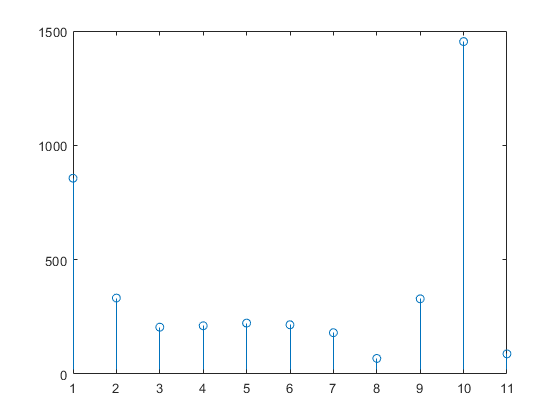


stem(abs(icirculate))